Let's start by creating some data on which to perform inference.

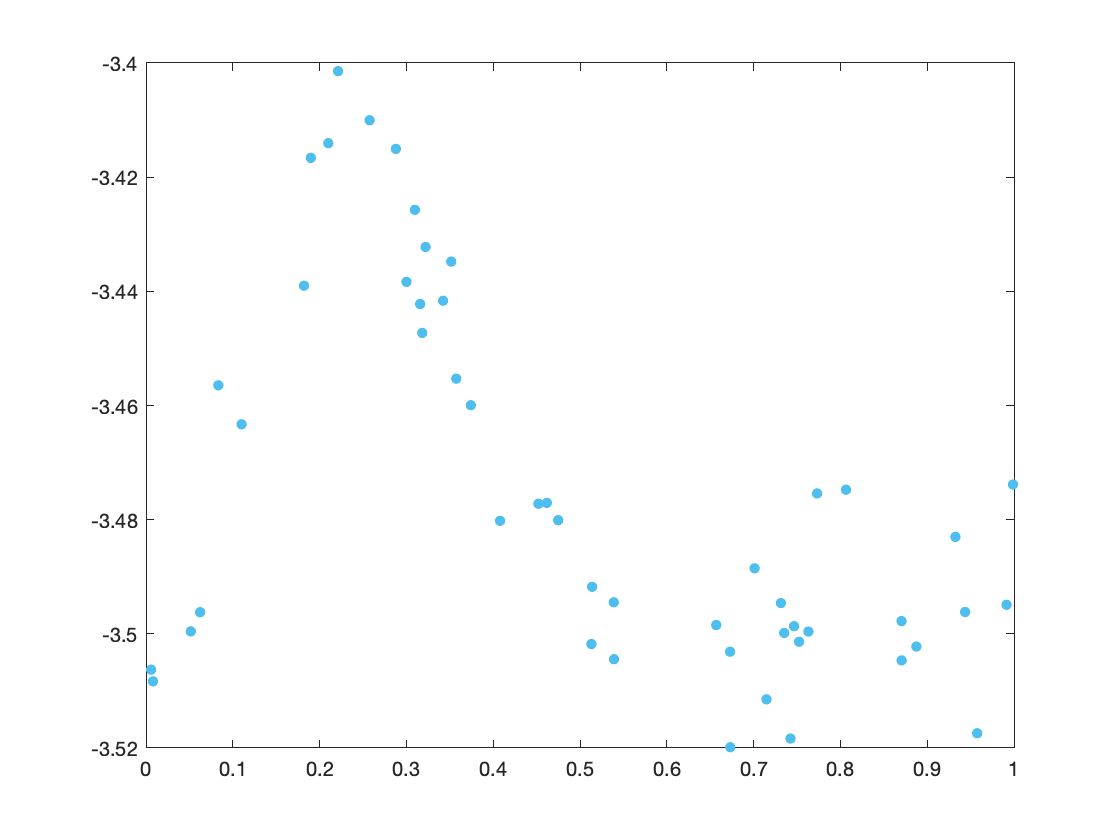

rng(14);
n=50;
x = sort(unifrnd(0,1,[1,n]));
errors = normrnd(0,0.01,[1,n]);
% Data simulation the same as from Perperoglou et al 2019.
y = -3.5+0.2.*x.^11.*10.*(1-x).^6+10.*(10.*x.^3).*(1-x).^10+errors;
plot(x,y,'.r','MarkerEdgeColor',[0.3010 0.7450 0.9330],'MarkerSize',15);

We'll select knots based on the graphic, although more principled methods exist.

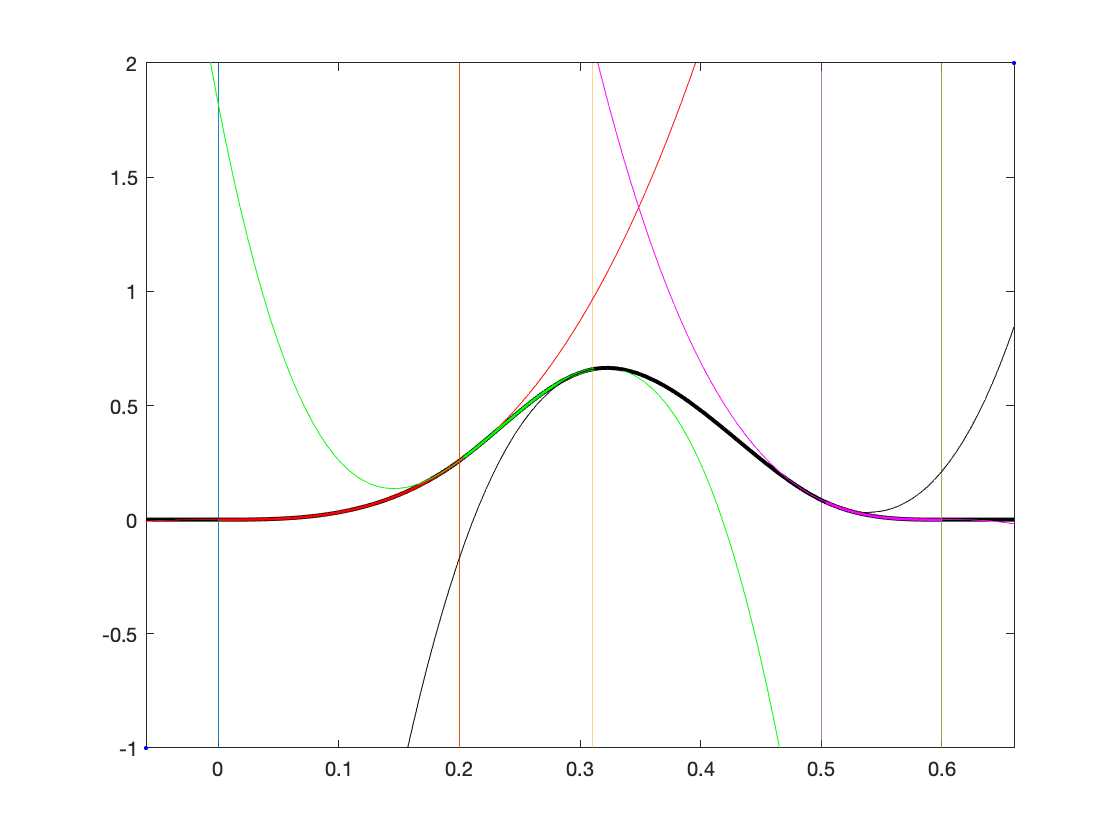

knots = [0.0, 0.2, 0.31, 0.5, 0.6];
bspline(knots) 

pp=bspline(knots);
pp.coefs

ans =    32.2581         0         0         0
 -195.0147   19.3548    3.8710    0.2581
  124.3194  -45.0000    1.0500    0.6585
  -86.2069   25.8621   -2.5862    0.0862


bspline_value = @(thetas, x_value) ()